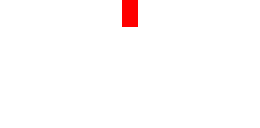

clear;close all;
load DQT.mat
load DHT.mat
% [AC_luminance_tag, ~, AC_luminance_code] = textread('AC_luminance.txt', '%s%s%s');
% [~, ~, DC_luminance_code] = textread('DC_luminance.txt', '%s%s%s');
% [AC_chrominance_tag, ~, AC_chrominance_code] = textread('AC_chrominance.txt', '%s%s%s');
% [~, ~, DC_chrominance_code] = textread('DC_chrominance.txt', '%s%s%s');
% pic_rgb = zeros(32, 16, 3);
% pic_rgb(:, :, 1) = 255;
pic_rgb = imread('1.jpg');
[real_row, real_column, ~] = size(pic_rgb);
imshow(pic_rgb)

% imwrite(uint8(pic_rgb), '1.jpg')

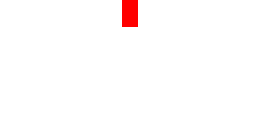

% 将图片的尺寸归一化为8的倍数
pic_rgb_normalized = pic_normalize(pic_rgb);
[row, column, ~] = size(pic_rgb_normalized);
imshow(pic_rgb_normalized)

% 图片中心化
pic_rgb_centered = pic_rgb_normalized - 128;
% 变换为ycbcr空间
pic_ycbcr = rgb2ycbcr(pic_rgb_centered);

% 进行DCT变换
func = @dct2;
pic_y = blkproc(pic_ycbcr(:, :, 1), [8 8], func);
pic_cb = blkproc(pic_ycbcr(:, :, 2), [8 8], func);
pic_cr = blkproc(pic_ycbcr(:, :, 3), [8 8], func);

% 量化
pic_y_quant = round(pic_y ./ repmat(DQT_y, row / 8, column / 8));
pic_cb_quant = round(pic_cb ./ repmat(DQT_cbcr, row / 8, column / 8));
pic_cr_quant = round(pic_cr ./ repmat(DQT_cbcr, row / 8, column / 8));

% z扫描
count = 1;
m = row * column / 64;
pic_zigzag_y = zeros(m, 64);
pic_zigzag_cb = zeros(m, 64);
pic_zigzag_cr = zeros(m, 64);
for r = (0 : row / 8 - 1)
    for c = (0 : column / 8 - 1)
        pic_zigzag_y(count, :) = zigzag(pic_y_quant(r * 8 + 1 : (r + 1) * 8, c * 8 + 1 : (c + 1) * 8));
        pic_zigzag_cb(count, :) = zigzag(pic_cb_quant(r * 8 + 1 : (r + 1) * 8, c * 8 + 1 : (c + 1) * 8));
        pic_zigzag_cr(count, :) = zigzag(pic_cr_quant(r * 8 + 1 : (r + 1) * 8, c * 8 + 1 : (c + 1) * 8));
        count = count + 1;
    end
end

% 编码 ycbcr
code_y = code_item(DC_luminance_code, AC_luminance_code, AC_luminance_tag, pic_zigzag_y, m, '11111111001', '1010');
code_cb = code_item(DC_chrominance_code, AC_chrominance_code, AC_chrominance_tag, pic_zigzag_cb, m, '1111111010', '00');
code_cr = code_item(DC_chrominance_code, AC_chrominance_code, AC_chrominance_tag, pic_zigzag_cr, m, '1111111010', '00');
save encode.mat code_y code_cb code_cr m row column real_column real_row -mat;
save real.mat pic_zigzag_y pic_zigzag_cb pic_zigzag_cr -mat;
